clear
close all
clc


% *** 実験実習で測定計測したデータ を load***
fileName = 'JumpData_S01' ; % ←　被験者番号を指定する
load(fileName) ;

% grf, Markers, cop が構造体としてまとめられているので、別々の変数として定義する
JumpData = JumpDataStruct.CMJ(1) ; % ←　条件名・試行番号を指定する
grfs = JumpData.Forces ;
Markers = JumpData.Markers ;
cop = JumpData.CoP ;
% ****



# **スティックピクチャ**

スティックピクチャを作成すると、どのような動作なのか分かりやすい

※　各フレームの xyz 座標データを plot, plot3 関数に与えてお絵描きをするだけなのだが、そこそこ面倒なので、進矢の作成した stickPicture 関数を使ってください

※　stickPicture は、マーカー座標データが、構造体として格納されていることが前提

※　プログラミングに慣れてきたら、使いやすいように自作してください

**※　2024年度のデモ用データ（DemoDataSJ.mat） と 2026年度の実験実習のデータ（Data_S01.matなど）では、マーカーの変数名が異なる **

**e.g., Shoulder → RShoulder など。**

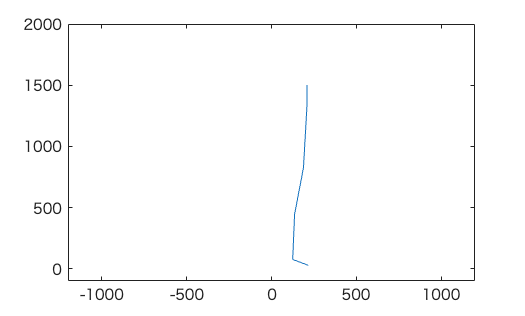

% プロットするマーカー名をセル配列で指定する
MarkerNames = {'REar', 'RShoulder', 'RGt', 'RKnee', 'RAnkle', 'RToe'} ;

% プロットしたいフレーム番号を指定する　（時系列が縦に並んでいることを想定しているので、行番号）
iFrame = 1 ;

% stickPicture 関数（自作）をコール
stickPicture(Markers, MarkerNames, iFrame, 'yz') ; % 4つめの引数 'yz' で、矢状面プロットを指定している
set(gca, 'xlim', [-1200,1200], 'ylim', [-100, 2000])

# **応用例: 時系列が分かるように、複数のスティックピクチャを重ね書き**

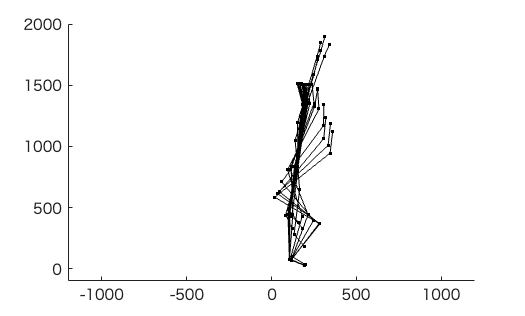

figure; hold on
% どの時刻からどの時刻までを、どれくらいの時間刻みにプロットするか
startFrame = 4000 ;
endFrame = 7000 ;
dt = 100 ;

for iFrame = [startFrame:dt:endFrame] % 繰り返し実行のプログラミング：　for loop
    % 最後の引数、'k.-' は、黒のドットを実線で結ぶ、を意味する
    % 'ro:' などを試してみるとよい（赤の丸を点線で結ぶ）
    stickPicture(Markers, MarkerNames, iFrame, 'yz', 'k.-') ; 
    
end
set(gca, 'xlim', [-1200,1200], 'ylim', [-100, 2000])

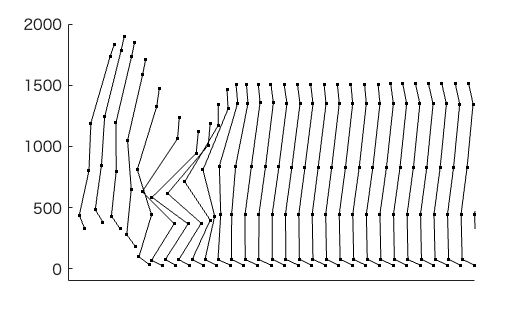


figure; hold on
MarkerFieldNames = fieldnames(Markers) ;
Markers2 = Markers ;
for iFrame = [startFrame:dt:endFrame] % 繰り返し実行のプログラミング：　for loop
    for iMarker = 1:length(MarkerFieldNames)
        Markers2.(MarkerFieldNames{iMarker})(:,2) = Markers.(MarkerFieldNames{iMarker})(:,2) + iFrame ;
    end
    stickPicture(Markers2, MarkerNames, iFrame, 'yz', 'k.-') ; 
end
set(gca, 'xlim', [startFrame, endFrame], 'ylim', [-100, 2000])
set(gca, 'xtick', [])

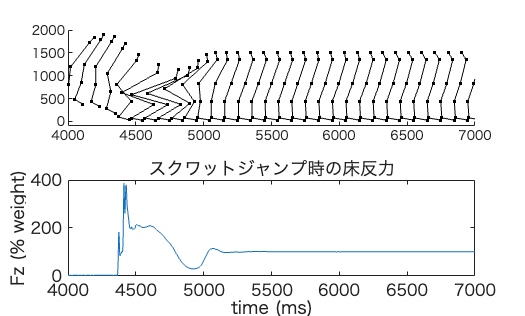

% 床反力データ
fzL = grfs(:,3) ; % 3列目は、左足が受けた床反力
fzR = grfs(:,6) ; % 6列目は、右足が受けた床反力
fz = fzL + fzR ;  % 左右の床反力を足して、身体が地面から受けた床反力
fzPercentWeight = fz * 100 ; % 100倍した方がグラフ的に見やすい説　（分かりやすい変数名にしておくこと）


figure;
subplot(2,1,1) ; hold on
MarkerFieldNames = fieldnames(Markers) ;
Markers2 = Markers ;
for iFrame = [startFrame:dt:endFrame] % 繰り返し実行のプログラミング：　for loop
    for iMarker = 1:length(MarkerFieldNames)
        Markers2.(MarkerFieldNames{iMarker})(:,2) = Markers.(MarkerFieldNames{iMarker})(:,2) - 150 + iFrame ;
    end
    stickPicture(Markers2, MarkerNames, iFrame, 'yz', 'k.-') ; 
end
set(gca, 'xlim', [startFrame,endFrame], 'ylim', [-100, 2000])
% set(gca, 'xtick', [])

subplot(2,1,2) ;
plot(fzPercentWeight)
ylabel('Fz (% weight)')
xlabel('time (ms)')
set(gca, 'fontsize', 12, 'fontname', 'meiryo')
set(gca, 'xlim', [startFrame,endFrame])
title('スクワットジャンプ時の床反力')